# ** PREDICCIÓN CON LSTM**

En este programa se va a prececir la evolución de un serie temporal mediante una red neuronal LSTM. Se simulará mediante las instrucciones específicas de definición de una red de "Deep Learning".

Se dispondrá de cuatro series temporales: el precio de los derechos de emisión de CO2, el consumo de energía eléctrica en la EII, el precio del barril de petroleo Brent y el precio del gas natural.

En primer lugarse cierran todas las ventana abiertas y se limpian todas las varibles.

close all
clear all

## **CARGA DE LOS DATOS **

Los datos están guardados en columnas, por lo que deben ser pasados a formato filas, que es como Matlab requiere que sean suministrados a las instrucciones de simulacion del LSTM.

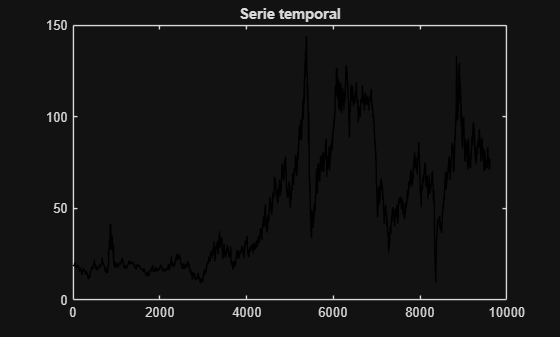

%serie0=readmatrix('Derechos_CO2.xlsx','Range','B2:B4555');
%serie0=xlsread('consumos_eii_2022.xlsx','L3:L8762');
serie0=readmatrix('Petroleo_Brent.xlsx','Range','B1:B9609');
%serie0=readmatrix('Gas_Natural.xlsx','Range','B4:B7097');
serie=serie0';

plot(serie,'k')
title('Serie temporal')

## **PARÁMETROS DE CONTROL**

La red que se va a simular tendrá únicamente una capa LSTM. Para determinar la estructura de la red es necesario proporcionar el **número de datos anteriores que se presentan a la red** (*numdatos*), el **número de neuronas de la capa LSTM** (*n*`umneuronas`) y la **distribución** de los datos entre  **entrenamiento y validación**, expresado en tanto por uno de entrenamiento. Se ajusta también el **número de los últimos datos predichos que se desea representar gráficamente** (*ultimdatos*). Esto se hace para tener una visión gráfica más detallada de la precisión de las predicciones, ya que la representación de todos los datos puede ser poco infomativa debido a su gran número.

numdatos=1;
numneuronas=10;
ultimdatos=100;
porcenEntVal=0.75;

## **ESTRUCTURA DE LA RED**

La lista con todas las posibilidades y opciones de capas para definir una red neuronal Deep Learning puede consultarse en la dirección:

[Lista de capas de deep learning](https://es.mathworks.com/help/releases/R2025b/deeplearning/ug/list-of-deep-learning-layers.html)

Al fial de la página hay una lista de temas que se pueden consultar para ver la forma de definir distintos modelos de Deep Learnig.

El primer paso para definir la red LSTM, y en general cualquier red de tipo Deep Learning, será definir la estructura en capas de la red.

Esa estructura se define mediante un vector, cuyos elementos representan las distintas capas de la misma. Esta estructura estará formada por:

- Capa de entrada de datos secuenciales ('*sequenceInputLayer'*). Cada vector de entrada tendrá *numdatos* componentes.

- Capa capa LSTM ('*lstmLayer'*) formada por *numneuronas*.

- Capa totalmente conectada, MLP, ('*fullyConnectedLayer'*) formada por una única neurona, ya que se va a predecir un único dato futuro.

- Capa de salida definida por una capa de regresión ya que el problema que se está tratandop es de este tipo ('*regressionLayer').*

layers=[ ...
sequenceInputLayer(numdatos)
lstmLayer(numneuronas)
fullyConnectedLayer(1)
regressionLayer];

A continuación se fijarán los distintos hiperparámetros que controlan el proceso de entrenamiento. No es necesario fijar todos estos hiperparámetros, basta con ajustar aquellos que se desee que tengan un valor diferente al fijado por defecto por Matlab. La lista completa se puede ver en la ayuda de la instrucción *'trainingOptions'. *Los ajustados aquí son:

- El entrenamiento (*'solver'*) se realizará con el algoritmo de Adam ("*adam*").

- Entorno de ejecuición. *'ExecutionEnvironment'='cpu'*,

- Tamaño de los lotes para el entrenamietno.* 'MinibatchSize'=128.*

- Número máximo de pasadas de entrenamiento a todos los datos. * 'MaxEpochs'=1000.*

- Umbral del gradiente para evitar que valores demasiado grandes generen problemas en el entrenamiento.* 'GradientThreshold'=1.*

- Tasa inicial de entrenamiento, que fija la precisión inicial del proceso, y que podrá variar a lo largo del mismo. *'InitialLearnRate'=0.005.*

- Número de simulaciones completas (*epochs*) necesarias para modifcar la tasa de aprendizaje. *'LearnRateDropPeriod'=125*.

- Factor para reducir la tasa de aprendizaje.* 'LearnRateDropFactor'=0.5*.

- Presentación de resultados intermedios del aprendizaje. *'Verbose'=1 p*ara que aparezcan y *0 *para que no.

- Repesentacióin gráfica de la evolución del error durante el aprendizaje. *'Plots'='training-progress' *para que aparezca y* 'none' *para que no.

options=trainingOptions('adam', ...
'ExecutionEnvironment','cpu', ...
'MinibatchSize',128,...
'MaxEpochs',1000, ...
'GradientThreshold',1, ...
'InitialLearnRate',0.005, ...
'LearnRateDropPeriod',125, ...
'LearnRateDropFactor',0.5, ...
'Verbose',0,...
'Plots','none');

Por simplicidad, para este caso concreto no se utilizarán los datos en el formato "*dlarray*" ni la instrucción de creación de la red neruonal mediante el comando "*dlnetwork*" . La creación de la red con la estructura e hiperparámetros seleccionados se realizará de forma automática al invocar la instrucción de entrenamiento "*trainNetwork*".

Se fija la semilla del generador de numeros aleatorios para que siempre se genere la misma secuencia aleatoria de inicio.

rng(1);

## ENTRENAMIENTO Y PREDICCIÓN DE LA SERIE

Índice que señala al último dato de la serie de entrenamiento.

longEntre=ceil(porcenEntVal*length(serie));

Serie con los datos reales que se utilizarán para validar los modelos:

serieVal=serie(longEntre+1:length(serie));

A diferencia de lo que ocurre con las redes MLP definidas de forma específica (práctica 1), las redes definidas de forma genérica mediante los comando de Deep Learning no normalizan los datos de forma automática, por lo que será necesario hacerlo antes de procesarlos.Se normalizan los datos restándoles la media y dividiéndolos por la desviación estándar. El proceso inverso deberá realizarse con los resultados obtenidos de la predicción.

mu=mean(serie);
sig=std(serie);
serieNorm=(serie-mu)/sig;

**DATOS DE ENTRENAMIENTO**

Se forman los vectores de entrenamiento: datos de entrada y valor esperado de la salida.

for k=1:1:longEntre-numdatos
    patronEntr(:,k)=serieNorm(k:k+numdatos-1);
    patronSal(:,k)=serieNorm(k+numdatos);
end

**DATOS DE VALIDACIÓN**

Se forman los vectores de entrada que se utilizaran para validar la capacidad de predicción de la red neruonal.

for k=longEntre:1:length(serieNorm)-1
    patronPred(:,k-longEntre+1)=serieNorm(k-numdatos+1:k);
end

**ENTRENAMIENTO Y PREDICCIÓN**

Cuando se simula una red LSTM suele ser interesante resetearla (se borran los estado internos, pero no los pesos aprendidos) primero y alimentarla con datos anteriores a los que se van a predecir para tener "recuerdos" del comportamiento anterior de la serie. Sin embargo, cuando los datos que se van a predecir son los inmediatamtne siguientes a los que se utilizaron para el entrenamiento, estos dos pasos no son necesarios, ya que los "recuerdos" almacenados son los de los datos inmediatemente anteriores a los que se van a predecir.

Solo a título informativo, se activa un reloj interno para saber el tiempo que consume todo el proceso de simulación de la red neuronal.

tic
reddepred=trainNetwork(patronEntr,patronSal,layers,options);
[reddepred,prediccionesNorm]=predictAndUpdateState(reddepred,patronPred,'ExecutionEnvironment','cpu');

Los datos predichos se desnormalizan antes de analizar los resultados.

predicciones=sig*prediccionesNorm+mu;
toc

Elapsed time is 13.594001 seconds.


## **PRESENTACIÓN DE LOS RESULTADOS**

**PRESENTACIÓN GRÁFICA DE LOS RESULTADOS**

Se generarán tres gráficas: compartiva de todos los datos predichos con sus valores reales, comparativa de los últimos datos predichos con su valores reales y errores cometidos en las predicciones.

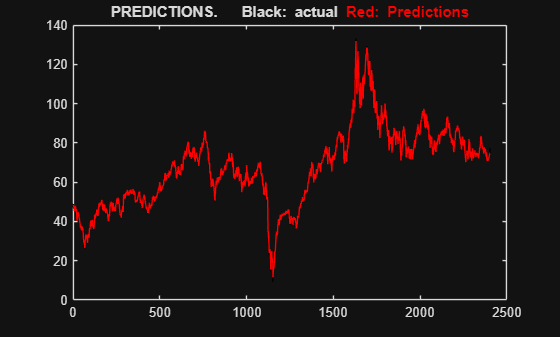

plot(serie(longEntre+1:length(serie)),'k')
hold on
plot(predicciones,'r')
title('PREDICTIONS.   Black: actual \color{red}Red: Predictions')
hold off

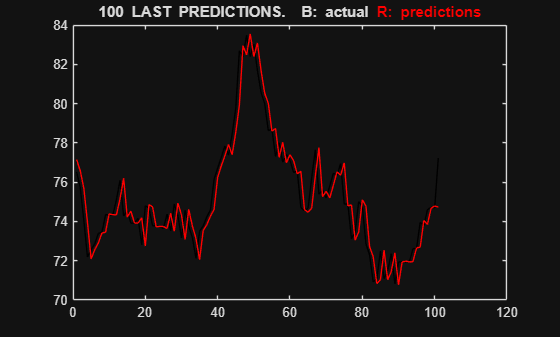

plot(serie(length(serie)-ultimdatos:length(serie)),'k')
hold on
plot(predicciones(length(predicciones)-ultimdatos:length(predicciones)),'r')
title([num2str(ultimdatos),' LAST PREDICTIONS.  B: actual \color{red}R: predictions'])
hold off

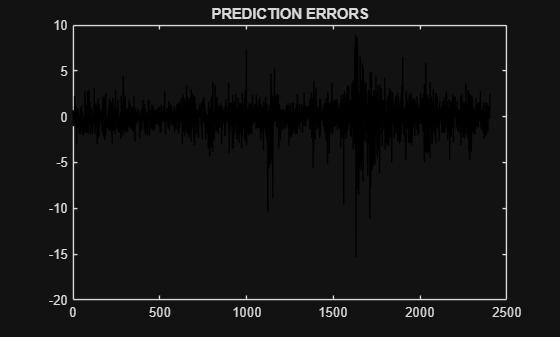

error=serieVal-predicciones;

plot(error,'k')
title('PREDICTION ERRORS')

**TABLA DE ERRORES**

Cálculo de todas las métricas de error que miden las prestaciones del modelo.

prestaciones(1,:)=calculoErr(serieVal,error);

Se organizan los datos para presentarlos en una tabla.

prestaciones=round(prestaciones,4);
MAPE=prestaciones(:,1);
MAE=prestaciones(:,2);
MSE=prestaciones(:,3);
RMSE=prestaciones(:,4);
R2=prestaciones(:,5);
MeanErr=prestaciones(:,6);
Std=prestaciones(:,7);

errores=table(MAPE,MAE,MSE,RMSE,R2,MeanErr,Std)

errores = 1×7 table
     MAPE      MAE       MSE       RMSE      R2      MeanErr     Std  
    ______    ______    ______    ______    _____    _______    ______

    1.8398    1.1409    2.7544    1.6597    0.993    -0.0627    1.6588


**FUNCION PARA CALCULAR LOS ÍNDICES DE ERROR**

Calcula los índices de error de las predicciones: MAPE, MAE, MSE, RMSE, R2, error medio y desviación estándar.

function [indice]=calculoErr(reales,errorAbs)
indice(1)=mean(abs(errorAbs./reales))*100;                        %MAPE
indice(2)=mean(abs(errorAbs));                                    %MAE
indice(3)=mean(errorAbs.^2);                                      %MSE
indice(4)=sqrt(indice(3));                                        %RMSE
indice(5)=1-sum(errorAbs.^2)./sum((reales-mean(reales)).^2);      %R2
indice(6)=mean(errorAbs);                                         %ERROR MEDIO
indice(7)=std(errorAbs);                                          %DESVIACIÓN ESTANDAR
end